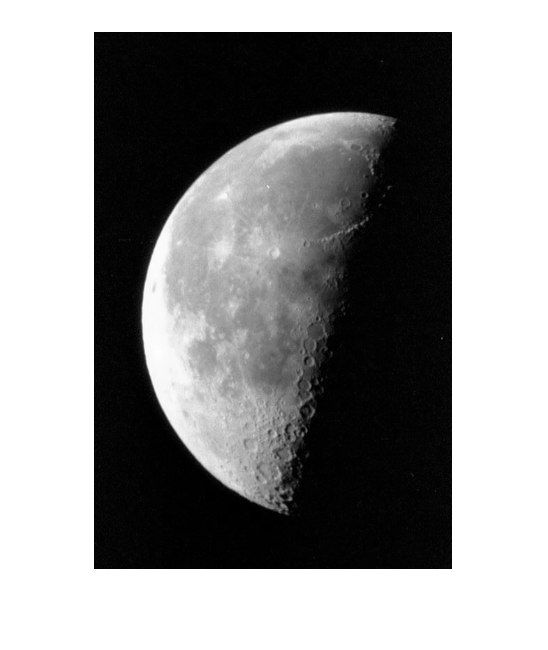

c = imread('images\moon.tif');
cd = double(c);
imshow(c)

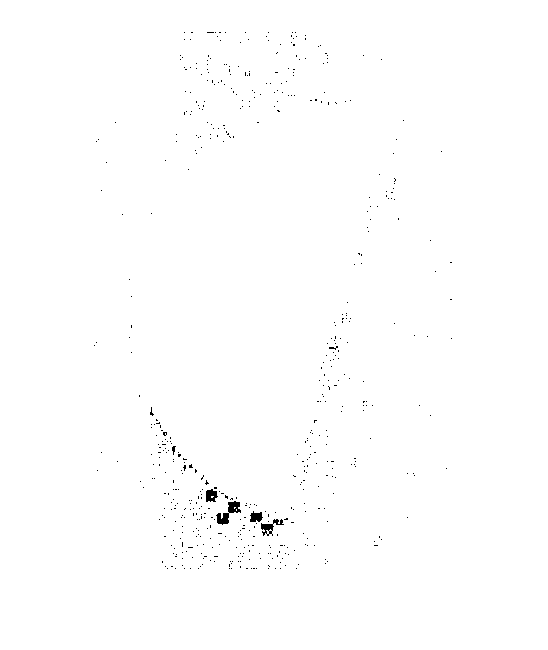

imshow(cd)

imshow(cd/255) % values for double should be in [0,1]

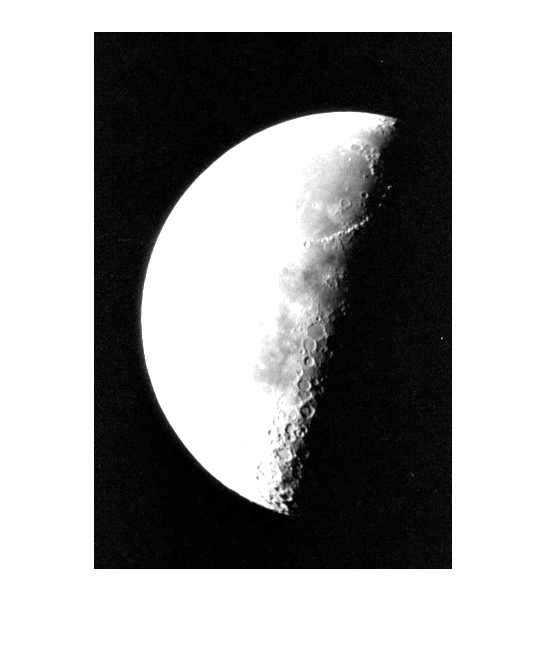

imshow(cd/128)

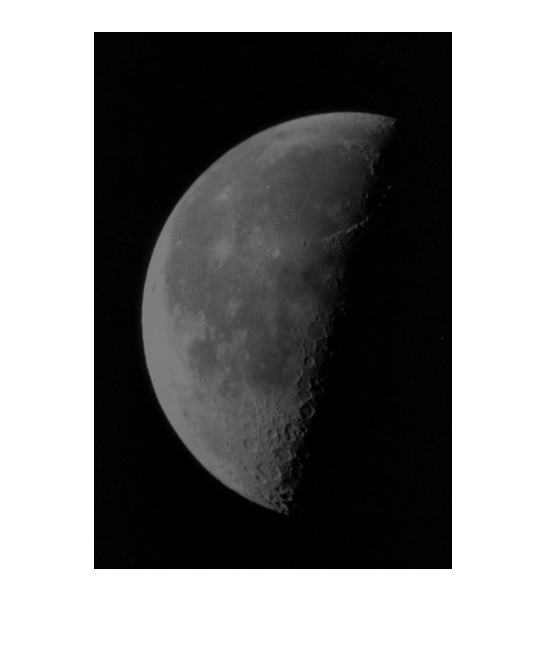

imshow(cd/512)

cd = im2double(c);
imshow(cd) % convert values and type to double

c2 = uint8(255*cd); % convert back to uint8
c3 = im2uint8(cd); % preferred method

a = uint8([0 80; 160 240])

a = 2×2 uint8 matrix
     0    80
   160   240


(a-10)*2

ans = 2×2 uint8 matrix
     0   140
   255   255


cl = c > 120;
whos c cl

  Name        Size              Bytes  Class      Attributes

  c         537x358            192246  uint8                
  cl        537x358            192246  logical              



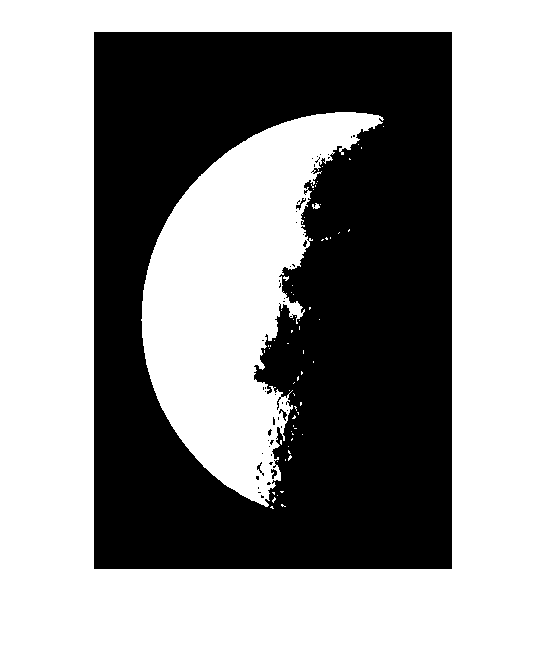

imshow(cl)

clu = uint8(cl);
whos clu

  Name        Size              Bytes  Class    Attributes

  clu       537x358            192246  uint8              



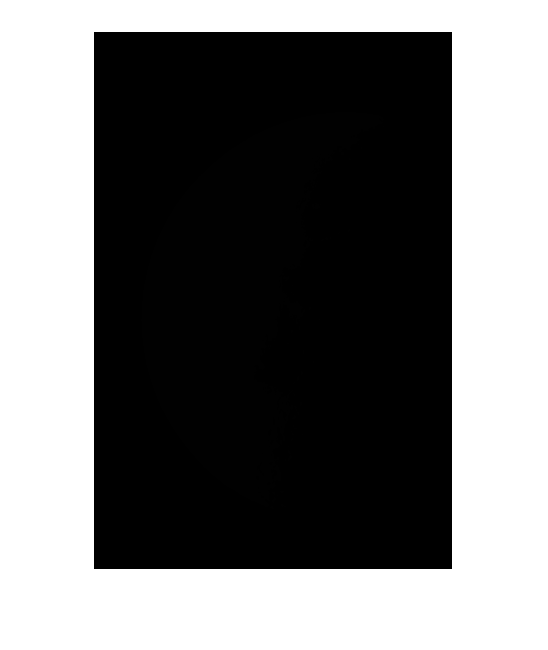

imshow(clu)

imshow(logical(clu))

imshow(double(clu))

Bit planes

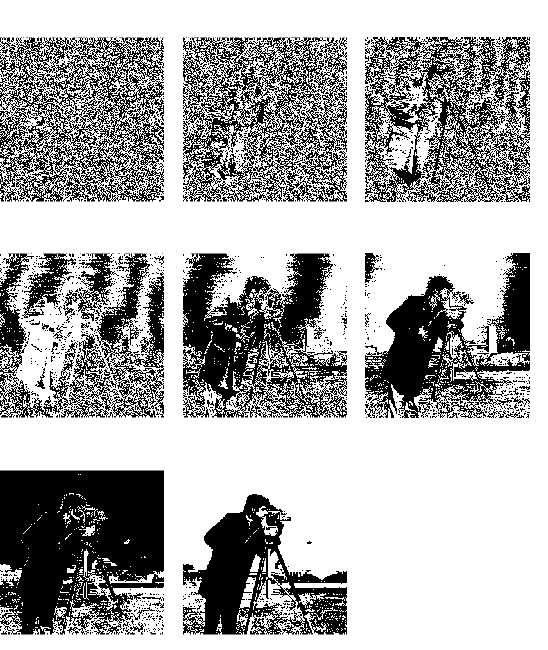

c = imread('images\cameraman.tif');
posx = [0 1 2 0 1 2 0 1] / 3;
posy = [2 2 2 1 1 1 0 0] / 3;
for i = 1:8
    subplot("position", [posx(i), posy(i), 0.3, 0.3]);
    imshow(logical(bitget(c,i)));
    axis image
end